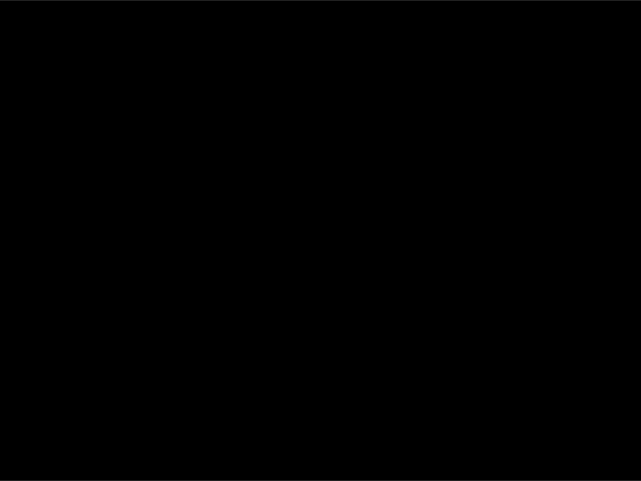

% 加载图像
img = imread('image_152.png');

% 将图像转换为灰度图像
grayImg = rgb2gray(img);

% 使用边缘算子（如Sobel算子）检测边缘
edges = edge(grayImg, 'Sobel',0.3);

% 显示边缘图像
figure;
imshow(edges);
title('Edge Detection using Sobel Operator');


% 计算每个通道的平均亮度
meanR = mean(mean(img(:,:,1))); % 红色通道
meanG = mean(mean(img(:,:,2))); % 绿色通道
meanB = mean(mean(img(:,:,3))); % 蓝色通道

% 判断颜色失真（简单假设：若某个通道平均值显著高于其他通道，可能存在 color cast）
threshold = 20; % 自定义阈值
if abs(meanR - meanG) > threshold || abs(meanR - meanB) > threshold || abs(meanG - meanB) > threshold
    disp('The image might have a color cast.');
else
    disp('The image is balanced in color channels.');
end

The image might have a color cast.
